## 基本

気象庁の毎時潮位観測資料は，地点ごとおよび月ごとにファイルが分かれています．

このため，観測地点名・年・月を入力してインスタンスを生成し，変数の初期化を行います．

tidegauge = JMAtide('東京', 2019, 10)

tidegauge =   JMAtide のプロパティ:

          station: '東京'
             year: 2019
            month: 10
             time: []
            ndays: []
              ssh: []
             ssha: []
              lon: 139.7667
              lat: 35.6500
          url_ssh: 'https://www.data.jma.go.jp/gmd/kaiyou/data/db/tide/genbo/2019/201910/hry201910TK.txt'
         url_ssha: 'https://www.data.jma.go.jp/gmd/kaiyou/data/db/tide/genbo/2019/201910/dep201910TK.txt'
             unit: 'cm'
    standard_time: 'JST(UTC+9)'


LoadSSH, LoadSSHA でそれぞれ潮位，潮位偏差を気象庁ウェブサイトから取得します．

格納されるプロパティ名は ssh と ssha です．

tidegauge = tidegauge.LoadSSH; % 潮位
tidegauge = tidegauge.LoadSSHA; % 潮位偏差

PlotSSH，PlotSSHA で取得したデータの簡易的なプロットが可能です．

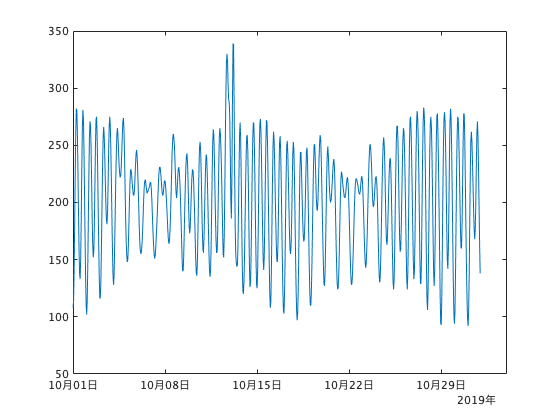

% 潮位のプロット
tidegauge.PlotSSH;

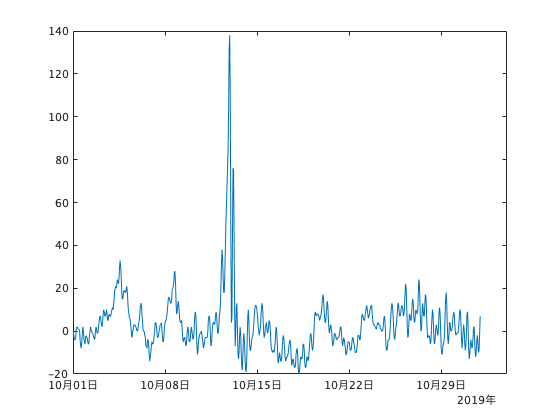

% 潮位偏差のプロット
tidegauge.PlotSSHA;

## 長期（２ヶ月以上）のデータ取得

年月の指定部分に配列を入力することで，長期間の潮位データを対象とすることが可能です．

tidegauge = JMAtide('東京', 2019); % 2019年1月〜12月, (1x12)配列
tidegauge = JMAtide('東京', [2018,09; 2019,10]); % 2018年9月 と 2019年10月, (1x2)配列
tidegauge = JMAtide('東京', 2019, 8:11) % 2019年9月〜11月, (1x4)配列

tidegauge =   1×4 JMAtide 配列のプロパティ:

    station
    year
    month
    time
    ndays
    ssh
    ssha
    lon
    lat
    url_ssh
    url_ssha
    unit
    standard_time


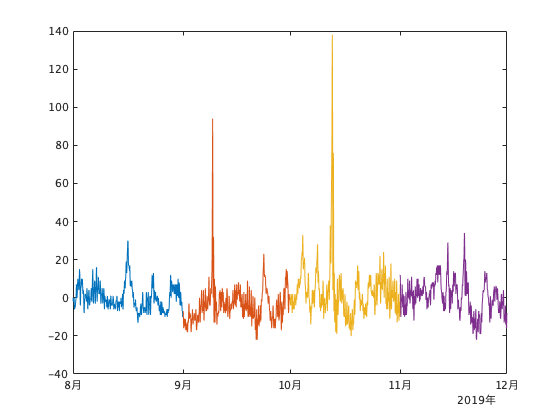

tidegauge = tidegauge.LoadSSHA;
tidegauge.PlotSSHA;

## 複数地点のデータ取得

地点名を cell 配列で複数指定すると，複数地点の潮位データを同時に扱えます．

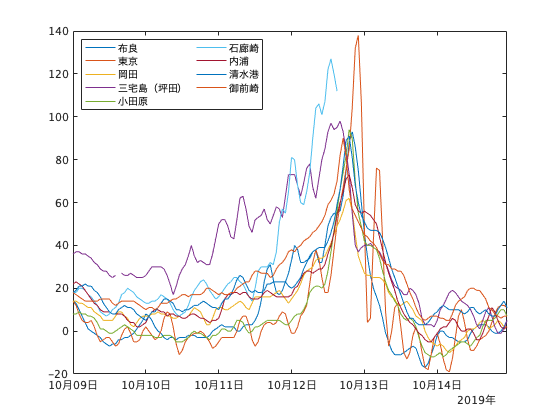

% 以下の9地点，2019年10月
tidegauge = JMAtide({'布良','東京','岡田','三宅島（坪田）','小田原','石廊崎','内浦','清水港','御前崎'}, 2019, 10);

% 潮位偏差取得
tidegauge = tidegauge.LoadSSHA;

% plot - 潮位偏差
lines = tidegauge.PlotSSHA;
xlim([tidegauge(1).time(24*8)+hours(1), tidegauge(1).time(24*14)])
legend(lines, {'布良','東京','岡田','三宅島（坪田）','小田原','石廊崎','内浦','清水港','御前崎'}, 'NumColumns',2, 'Location','NorthWest');